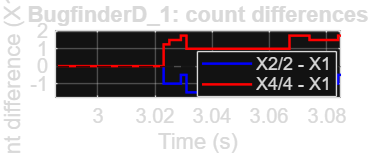

S = load('C:\Users\Admin\Desktop\RMX\Lab\encoder\data.mat');
name = 'BugfinderD_1';
ds = S.(name);

% อ่านตัวนับ X1/X2/X4 และแก้การวนค่า
counts = [];
for j = 1:3
    sig = getElement(ds, j+4);
    ts = sig.Values;
    t = ts.Time(:);
    raw = double(ts.Data(:));

    delta = mod(diff(raw)+32768,65536)-32768;
    counts(:,j) = [0; cumsum(delta)];
end

% เลือกช่วงที่ตัวนับเปลี่ยนเร็ว
dt = median(diff(t));
n = max(1,round(0.1/dt));
activity = movsum(abs(diff(counts(:,3))),n);
activity(t(2:end) < 1) = -Inf;
[~,idx] = max(activity);
center = t(idx+1);

limits = [max(t(1),center-0.05), min(t(end),center+0.05)];
keep = t >= limits(1) & t <= limits(2);
first = find(keep,1);

% ความต่างเทียบกับ X1 ในช่วงที่เลือก
difference = [counts(:,2)/2 - counts(:,1), ...
              counts(:,3)/4 - counts(:,1)];
difference = difference - difference(first,:);

figure('Color','w','Position',[100 100 1100 450]);
stairs(t(keep),difference(keep,1),'b','LineWidth',1.5);
hold on;
stairs(t(keep),difference(keep,2),'r','LineWidth',1.5);
yline(0,'--k','HandleVisibility','off');
grid on;

xlabel('Time (s)');
ylabel('Count difference (X1 units)');
legend('X2/2 - X1','X4/4 - X1','Location','best');
title([name ': count differences'],'Interpreter','none');
xlim(limits);

v = difference(keep,:);
margin = max(0.25,0.1*(max(v(:))-min(v(:))));
ylim([min(v(:))-margin, max(v(:))+margin]);
set(gca,'FontSize',12);

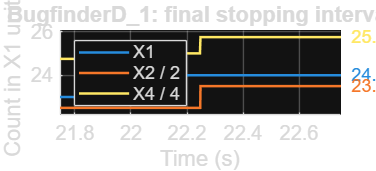

S = load('C:\Users\Admin\Desktop\RMX\Lab\encoder\data.mat');
name = 'BugfinderD_1';
ds = S.(name);

indices = [9 13 11]; % X1, X2, X4 หลังแก้ rollover
divisor = [1 2 4];
colors = lines(3);

figure('Color','w','Position',[100 100 1100 500]);
hold on;

finalValues = zeros(1,3);
allTime = cell(1,3);
allData = cell(1,3);
lastChange = zeros(1,3);

for j = 1:3
    sig = getElement(ds, indices(j));
    ts = sig.Values;
    t = ts.Time(:);
    y = double(ts.Data(:)) / divisor(j);

    allTime{j} = t;
    allData{j} = y;
    finalValues(j) = y(end);

    idx = find(diff(y) ~= 0, 1, 'last');
    if isempty(idx)
        lastChange(j) = t(1);
    else
        lastChange(j) = t(idx+1);
    end

    stairs(t, y, 'Color',colors(j,:), 'LineWidth',1.5);
end

% โฟกัสช่วงก่อนและหลังตัวนับหยุดเปลี่ยน
stopTime = max(lastChange);
left = max(allTime{1}(1), stopTime-0.5);
right = min(allTime{1}(end), stopTime+0.5);
xlim([left right]);

% ปรับแกนตั้งตามข้อมูลในช่วงท้าย
visible = [];
for j = 1:3
    keep = allTime{j} >= left & allTime{j} <= right;
    visible = [visible; allData{j}(keep)];
end
margin = max(0.25, 0.1*range(visible));
ylim([min(visible)-margin, max(visible)+margin]);

% ระบุค่าสุดท้ายของแต่ละเส้น
for j = 1:3
    text(right, finalValues(j), ...
        sprintf('  %.2f',finalValues(j)), ...
        'Color',colors(j,:), 'FontSize',11, ...
        'VerticalAlignment','middle');
end

grid on;
xlabel('Time (s)');
ylabel('Count in X1 units');
legend('X1','X2 / 2','X4 / 4','Location','best');
title([name ': final stopping interval'],'Interpreter','none');
ax = gca;
ax.YAxis.Exponent = 0;
set(gca,'FontSize',12);